## Analysis Pipeline for PEP WP-4 EEG Project

### House keeping

clc; clear; close all;%dbstop if error;
cfg = struct;
d = struct;

% add functions folder to path
cfg.functionPath = fullfile(pwd,'utilities');
addpath(genpath(cfg.functionPath))

### Define to-be-analyzed subjects

%cfg.subNums = [101:103, 105:106, 108:117, 119:122, 124, 126:130, 133];
%cfg.subNums = [101:103, 105:106, 108:117, 119:122, 124, 126:131, 133, 141:142]; 
cfg.subNums = [101:103, 105:106, 108:113, 115:117, 119:120, 122, 124, 128:131, 133, 141:142]; 
%cfg.subNums = [101:103, 105:106, 108:113, 115:117, 119:120, 122, 124, 128:131, 133]; 
cfg.FontSize = 20;
cfg = defaultCfg(cfg);

% Also did MRI but have different electrode placement 
%121
%126
%114
%127



### Preprocessing

disp(['Running pre-processing...' newline]);

Running pre-processing...



preprocess_EEG(cfg);

Pre-processed data for sub-101 exist already

Pre-processed data for sub-102 exist already

Pre-processed data for sub-103 exist already

Pre-processed data for sub-105 exist already

Pre-processed data for sub-106 exist already

Pre-processed data for sub-108 exist already

Pre-processed data for sub-109 exist already

Pre-processed data for sub-110 exist already

Pre-processed data for sub-111 exist already

Pre-processed data for sub-112 exist already

Pre-processed data for sub-113 exist already

Pre-processed data for sub-115 exist already

Pre-processed data for sub-116 exist already

Pre-processed data for sub-117 exist already

Pre-processed data for sub-119 exist already

Pre-processed data for sub-120 exist already

Pre-processed data for sub-122 exist already

Pre-processed data for sub-124 exist already

Pre-processed data for sub-128 exist already

Pre-processed data for sub-129 exist already

Pre-processed data for sub-130 exist already

Pre-processed data for sub-131 exi


% tfa
runTFA_bandwise(cfg)

the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 5 (11.72 Hz), 1 tapers

the call to "ft_freqanalysis" took 6 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 9 (28.91 Hz), 1 tapers

the call to "ft_freqanalysis" took 9 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 20 (68.75 Hz), 4 tapers

the call to "ft_freqanalysis" took 40 seconds
the input is freq data with 62 channels, 5 frequencybins and 2 timebins
the input is freq data with 62 channels, 9 frequencybins and 2 timebins
the input is freq data with 62 channels, 20 frequencybins and 2 timebins
concatenating over the "freq" dimension
the

the call to "ft_appendfreq" took 0 seconds
the input is timelock data with 63 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 5 (11.72 Hz), 1 tapers

the call to "ft_freqanalysis" took 6 seconds
the input is timelock data with 63 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 9 (28.91 Hz), 1 tapers

the call to "ft_freqanalysis" took 9 seconds
the input is timelock data with 63 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 20 (68.75 Hz), 4 tapers

the call to "ft_freqanalysis" took 41 seconds
the input is freq data with 63 channels, 5 frequencybins and 2 timebins
the input is freq data with 63 channels, 9 frequencybins and 2 timebins
the input is freq data with 63 channels, 20 frequencybins and 2 timebins


the call to "ft_appendfreq" took 0 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 5 (11.72 Hz), 1 tapers

the call to "ft_freqanalysis" took 6 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 9 (28.91 Hz), 1 tapers

the call to "ft_freqanalysis" took 9 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 20 (68.75 Hz), 4 tapers

the call to "ft_freqanalysis" took 41 seconds
the input is freq data with 62 channels, 5 frequencybins and 2 timebins
the input is freq data with 62 channels, 9 frequencybins and 2 timebins
the input is freq data with 62 channels, 20 frequencybins and 2 timebins


the call to "ft_appendfreq" took 0 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 5 (11.72 Hz), 1 tapers

the call to "ft_freqanalysis" took 6 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 9 (28.91 Hz), 1 tapers

the call to "ft_freqanalysis" took 9 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 20 (68.75 Hz), 4 tapers

the call to "ft_freqanalysis" took 41 seconds
the input is freq data with 62 channels, 5 frequencybins and 2 timebins
the input is freq data with 62 channels, 9 frequencybins and 2 timebins
the input is freq data with 62 channels, 20 frequencybins and 2 timebins


the call to "ft_appendfreq" took 0 seconds
the input is timelock data with 63 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 5 (11.72 Hz), 1 tapers

the call to "ft_freqanalysis" took 6 seconds
the input is timelock data with 63 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 9 (28.91 Hz), 1 tapers

the call to "ft_freqanalysis" took 10 seconds
the input is timelock data with 63 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 20 (68.75 Hz), 4 tapers

the call to "ft_freqanalysis" took 41 seconds
the input is freq data with 63 channels, 5 frequencybins and 2 timebins
the input is freq data with 63 channels, 9 frequencybins and 2 timebins
the input is freq data with 63 channels, 20 frequencybins and 2 timebins

the call to "ft_appendfreq" took 0 seconds
the input is timelock data with 63 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 5 (11.72 Hz), 1 tapers

the call to "ft_freqanalysis" took 6 seconds
the input is timelock data with 63 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 9 (28.91 Hz), 1 tapers

the call to "ft_freqanalysis" took 9 seconds
the input is timelock data with 63 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 20 (68.75 Hz), 4 tapers

the call to "ft_freqanalysis" took 40 seconds
the input is freq data with 63 channels, 5 frequencybins and 2 timebins
the input is freq data with 63 channels, 9 frequencybins and 2 timebins
the input is freq data with 63 channels, 20 frequencybins and 2 timebins


the call to "ft_appendfreq" took 0 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 5 (11.72 Hz), 1 tapers

the call to "ft_freqanalysis" took 6 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 9 (28.91 Hz), 1 tapers

the call to "ft_freqanalysis" took 9 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 20 (68.75 Hz), 4 tapers

the call to "ft_freqanalysis" took 41 seconds
the input is freq data with 62 channels, 5 frequencybins and 2 timebins
the input is freq data with 62 channels, 9 frequencybins and 2 timebins
the input is freq data with 62 channels, 20 frequencybins and 2 timebins


the call to "ft_appendfreq" took 0 seconds
the input is timelock data with 60 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 5 (11.72 Hz), 1 tapers

the call to "ft_freqanalysis" took 6 seconds
the input is timelock data with 60 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 9 (28.91 Hz), 1 tapers

the call to "ft_freqanalysis" took 9 seconds
the input is timelock data with 60 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 20 (68.75 Hz), 4 tapers

the call to "ft_freqanalysis" took 39 seconds
the input is freq data with 60 channels, 5 frequencybins and 2 timebins
the input is freq data with 60 channels, 9 frequencybins and 2 timebins
the input is freq data with 60 channels, 20 frequencybins and 2 timebins


the call to "ft_appendfreq" took 0 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 5 (11.72 Hz), 1 tapers

the call to "ft_freqanalysis" took 6 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 9 (28.91 Hz), 1 tapers

the call to "ft_freqanalysis" took 9 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 20 (68.75 Hz), 4 tapers

the call to "ft_freqanalysis" took 41 seconds
the input is freq data with 62 channels, 5 frequencybins and 2 timebins
the input is freq data with 62 channels, 9 frequencybins and 2 timebins
the input is freq data with 62 channels, 20 frequencybins and 2 timebins


the call to "ft_appendfreq" took 0 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 5 (11.72 Hz), 1 tapers

the call to "ft_freqanalysis" took 6 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 9 (28.91 Hz), 1 tapers

the call to "ft_freqanalysis" took 10 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 20 (68.75 Hz), 4 tapers

the call to "ft_freqanalysis" took 42 seconds
the input is freq data with 62 channels, 5 frequencybins and 2 timebins
the input is freq data with 62 channels, 9 frequencybins and 2 timebins
the input is freq data with 62 channels, 20 frequencybins and 2 timebins

the call to "ft_appendfreq" took 0 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 5 (11.72 Hz), 1 tapers

the call to "ft_freqanalysis" took 6 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 9 (28.91 Hz), 1 tapers

the call to "ft_freqanalysis" took 10 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 20 (68.75 Hz), 4 tapers

the call to "ft_freqanalysis" took 42 seconds
the input is freq data with 62 channels, 5 frequencybins and 2 timebins
the input is freq data with 62 channels, 9 frequencybins and 2 timebins
the input is freq data with 62 channels, 20 frequencybins and 2 timebins

the call to "ft_appendfreq" took 0 seconds
the input is timelock data with 61 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 5 (11.72 Hz), 1 tapers

the call to "ft_freqanalysis" took 6 seconds
the input is timelock data with 61 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 9 (28.91 Hz), 1 tapers

the call to "ft_freqanalysis" took 10 seconds
the input is timelock data with 61 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 20 (68.75 Hz), 4 tapers

the call to "ft_freqanalysis" took 41 seconds
the input is freq data with 61 channels, 5 frequencybins and 2 timebins
the input is freq data with 61 channels, 9 frequencybins and 2 timebins
the input is freq data with 61 channels, 20 frequencybins and 2 timebins

the call to "ft_appendfreq" took 0 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 5 (11.72 Hz), 1 tapers

the call to "ft_freqanalysis" took 6 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 9 (28.91 Hz), 1 tapers

the call to "ft_freqanalysis" took 10 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 20 (68.75 Hz), 4 tapers

the call to "ft_freqanalysis" took 41 seconds
the input is freq data with 62 channels, 5 frequencybins and 2 timebins
the input is freq data with 62 channels, 9 frequencybins and 2 timebins
the input is freq data with 62 channels, 20 frequencybins and 2 timebins

the call to "ft_appendfreq" took 0 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 5 (11.72 Hz), 1 tapers

the call to "ft_freqanalysis" took 6 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 9 (28.91 Hz), 1 tapers

the call to "ft_freqanalysis" took 10 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 20 (68.75 Hz), 4 tapers

the call to "ft_freqanalysis" took 41 seconds
the input is freq data with 62 channels, 5 frequencybins and 2 timebins
the input is freq data with 62 channels, 9 frequencybins and 2 timebins
the input is freq data with 62 channels, 20 frequencybins and 2 timebins

the call to "ft_appendfreq" took 0 seconds
the input is timelock data with 63 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 5 (11.72 Hz), 1 tapers

the call to "ft_freqanalysis" took 6 seconds
the input is timelock data with 63 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 9 (28.91 Hz), 1 tapers

the call to "ft_freqanalysis" took 9 seconds
the input is timelock data with 63 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 20 (68.75 Hz), 4 tapers

the call to "ft_freqanalysis" took 41 seconds
the input is freq data with 63 channels, 5 frequencybins and 2 timebins
the input is freq data with 63 channels, 9 frequencybins and 2 timebins
the input is freq data with 63 channels, 20 frequencybins and 2 timebins


the call to "ft_appendfreq" took 0 seconds
the input is timelock data with 63 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 5 (11.72 Hz), 1 tapers

the call to "ft_freqanalysis" took 6 seconds
the input is timelock data with 63 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 9 (28.91 Hz), 1 tapers

the call to "ft_freqanalysis" took 9 seconds
the input is timelock data with 63 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 20 (68.75 Hz), 4 tapers

the call to "ft_freqanalysis" took 47 seconds
the input is freq data with 63 channels, 5 frequencybins and 2 timebins
the input is freq data with 63 channels, 9 frequencybins and 2 timebins
the input is freq data with 63 channels, 20 frequencybins and 2 timebins


the call to "ft_appendfreq" took 0 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 5 (11.72 Hz), 1 tapers

the call to "ft_freqanalysis" took 6 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 9 (28.91 Hz), 1 tapers

the call to "ft_freqanalysis" took 9 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 20 (68.75 Hz), 4 tapers

the call to "ft_freqanalysis" took 42 seconds
the input is freq data with 62 channels, 5 frequencybins and 2 timebins
the input is freq data with 62 channels, 9 frequencybins and 2 timebins
the input is freq data with 62 channels, 20 frequencybins and 2 timebins


the call to "ft_appendfreq" took 0 seconds
the input is timelock data with 63 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 5 (11.72 Hz), 1 tapers

the call to "ft_freqanalysis" took 6 seconds
the input is timelock data with 63 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 9 (28.91 Hz), 1 tapers

the call to "ft_freqanalysis" took 9 seconds
the input is timelock data with 63 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 20 (68.75 Hz), 4 tapers

the call to "ft_freqanalysis" took 41 seconds
the input is freq data with 63 channels, 5 frequencybins and 2 timebins
the input is freq data with 63 channels, 9 frequencybins and 2 timebins
the input is freq data with 63 channels, 20 frequencybins and 2 timebins


the call to "ft_appendfreq" took 0 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 5 (11.72 Hz), 1 tapers

the call to "ft_freqanalysis" took 6 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 9 (28.91 Hz), 1 tapers

the call to "ft_freqanalysis" took 10 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 20 (68.75 Hz), 4 tapers

the call to "ft_freqanalysis" took 41 seconds
the input is freq data with 62 channels, 5 frequencybins and 2 timebins
the input is freq data with 62 channels, 9 frequencybins and 2 timebins
the input is freq data with 62 channels, 20 frequencybins and 2 timebins

the call to "ft_appendfreq" took 0 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 5 (11.72 Hz), 1 tapers

the call to "ft_freqanalysis" took 6 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 9 (28.91 Hz), 1 tapers

the call to "ft_freqanalysis" took 9 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 20 (68.75 Hz), 4 tapers

the call to "ft_freqanalysis" took 41 seconds
the input is freq data with 62 channels, 5 frequencybins and 2 timebins
the input is freq data with 62 channels, 9 frequencybins and 2 timebins
the input is freq data with 62 channels, 20 frequencybins and 2 timebins


the call to "ft_appendfreq" took 0 seconds
the input is timelock data with 63 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 5 (11.72 Hz), 1 tapers

the call to "ft_freqanalysis" took 6 seconds
the input is timelock data with 63 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 9 (28.91 Hz), 1 tapers

the call to "ft_freqanalysis" took 9 seconds
the input is timelock data with 63 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 20 (68.75 Hz), 4 tapers

the call to "ft_freqanalysis" took 41 seconds
the input is freq data with 63 channels, 5 frequencybins and 2 timebins
the input is freq data with 63 channels, 9 frequencybins and 2 timebins
the input is freq data with 63 channels, 20 frequencybins and 2 timebins


the call to "ft_appendfreq" took 0 seconds
the input is timelock data with 63 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 5 (11.72 Hz), 1 tapers

the call to "ft_freqanalysis" took 6 seconds
the input is timelock data with 63 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 9 (28.91 Hz), 1 tapers

the call to "ft_freqanalysis" took 9 seconds
the input is timelock data with 63 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 20 (68.75 Hz), 4 tapers

the call to "ft_freqanalysis" took 41 seconds
the input is freq data with 63 channels, 5 frequencybins and 2 timebins
the input is freq data with 63 channels, 9 frequencybins and 2 timebins
the input is freq data with 63 channels, 20 frequencybins and 2 timebins


the call to "ft_appendfreq" took 0 seconds
the input is timelock data with 63 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 5 (11.72 Hz), 1 tapers

the call to "ft_freqanalysis" took 6 seconds
the input is timelock data with 63 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 9 (28.91 Hz), 1 tapers

the call to "ft_freqanalysis" took 9 seconds
the input is timelock data with 63 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 20 (68.75 Hz), 4 tapers

the call to "ft_freqanalysis" took 41 seconds
the input is freq data with 63 channels, 5 frequencybins and 2 timebins
the input is freq data with 63 channels, 9 frequencybins and 2 timebins
the input is freq data with 63 channels, 20 frequencybins and 2 timebins


the call to "ft_appendfreq" took 0 seconds
the input is timelock data with 63 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 5 (11.72 Hz), 1 tapers

the call to "ft_freqanalysis" took 6 seconds
the input is timelock data with 63 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 9 (28.91 Hz), 1 tapers

the call to "ft_freqanalysis" took 9 seconds
the input is timelock data with 63 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 20 (68.75 Hz), 4 tapers

the call to "ft_freqanalysis" took 41 seconds
the input is freq data with 63 channels, 5 frequencybins and 2 timebins
the input is freq data with 63 channels, 9 frequencybins and 2 timebins
the input is freq data with 63 channels, 20 frequencybins and 2 timebins


the call to "ft_appendfreq" took 0 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 5 (11.72 Hz), 1 tapers

the call to "ft_freqanalysis" took 6 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 9 (28.91 Hz), 1 tapers

the call to "ft_freqanalysis" took 9 seconds
the input is timelock data with 62 channels and 200 timebins
constructing trials from "trial"
the call to "ft_selectdata" took 0 seconds
processing trials
trial 2000, frequency 20 (68.75 Hz), 4 tapers

the call to "ft_freqanalysis" took 41 seconds
the input is freq data with 62 channels, 5 frequencybins and 2 timebins
the input is freq data with 62 channels, 9 frequencybins and 2 timebins
the input is freq data with 62 channels, 20 frequencybins and 2 timebins


the call to "ft_appendfreq" took 0 seconds


### Category decoding

disp(['Running decoding...' newline]);

Running decoding...



%decoding_EEG(cfg);

### Individual decoding accuracies

disp(['Running individual decoding...' newline]);

Running individual decoding...



%individual_decoding_accuracies(cfg);

### Pairwise decoding

cfg.plotting = false;
cfg.plot_rdm = false;
cfg.pca = true;
cfg.nTrials2average = 2;
disp(['Running pairwise decoding...' newline]);

Running pairwise decoding...



[d.pairRep, d.meanAcc, cfg] = PairwiseTPLDAclassifier(cfg);

RDM for sub-101 already exists
RDM for sub-102 already exists
RDM for sub-103 already exists
RDM for sub-105 already exists
RDM for sub-106 already exists
RDM for sub-108 already exists
RDM for sub-109 already exists
RDM for sub-110 already exists
RDM for sub-111 already exists
RDM for sub-112 already exists
RDM for sub-113 already exists
RDM for sub-115 already exists
RDM for sub-116 already exists
RDM for sub-117 already exists
RDM for sub-119 already exists
RDM for sub-120 already exists
RDM for sub-122 already exists
RDM for sub-124 already exists
RDM for sub-128 already exists
RDM for sub-129 already exists
RDM for sub-130 already exists
RDM for sub-131 already exists
RDM for sub-133 already exists



% stats and plotting
cfg.plotting = true;
cfg.alpha = 0.01;
disp(['Running t-test on pairwise decoding accuracies...' newline]);

Running t-test on pairwise decoding accuracies...



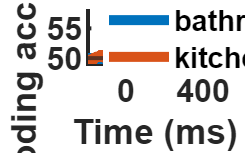

stats_ttest(cfg, d);

### ISC of representation

cfg.plotting = true;
cfg.plot_rdm = false;
cfg.smoothing_window = 5;
cfg.regressOutMean = false;
cfg.dissimilarity = true;
cfg.ISC_types = {'pairRep'};
cfg.correlation_type = 'Spearman';
cfg.plot_sem = false;

% do permutation test
cfg.permutationtest = true;
cfg.n_permutations = 10000;
cfg.alpha = 0.05;
d.stats = struct;

disp(['Running ISC...' newline]);

Running ISC...



Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).


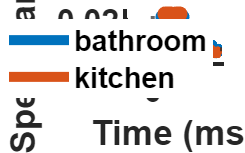

[d, d.stats.ISC] = getISCofRespresentation(cfg,d);

### ISC of representation with regressOutMean

cfg.plotting = true;
cfg.plot_rdm = false;
cfg.regressOutMean = true;
cfg.dissimilarity = true;
cfg.ISC_types = {'pairRep'};
cfg.correlation_type = 'Spearman';
cfg.new_figure = false;
cfg.permutationtest = false;
disp(['Running ISC...' newline]);

Running ISC...



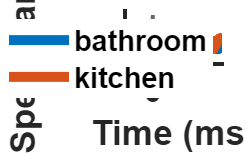

[d, ~] = getISCofRespresentation(cfg, d);

### Get inter-subject similarity on drawings

cfg.dnn = 'vgg16_imagenet';
cfg.layer_type = 'late';
%cfg.layer_type = 'early_mid';
cfg.correlation_type = 'Spearman';
cfg.dissimilarity = true;
cfg.plot_rdm = false;
cfg.MaxColorValue = 1;
cfg.new_figure = true;

% Create output directory if wanted
% output_dir = fullfile(pwd, '..', 'dnn_features');
% if exist(output_dir, 'dir')
%     rmdir(output_dir, 's');
% end

% get images
cfg.analysis_names = {'typical', 'control', 'photos'};
images = load_images(cfg);

Loaded image: 101_bat_gen1.png
Loaded image: 101_bat_gen2.png
Loaded image: 101_bat_gen3.png
Loaded image: 102_bat_gen1.png
Loaded image: 102_bat_gen2.png
Loaded image: 102_bat_gen3.png
Loaded image: 103_bat_gen1.png
Loaded image: 103_bat_gen2.png
Loaded image: 103_bat_gen3.png
Loaded image: 104_bat_gen1.png
Loaded image: 104_bat_gen2.png
Loaded image: 104_bat_gen3.png
Loaded image: 105_bat_gen1.png
Loaded image: 105_bat_gen2.png
Loaded image: 105_bat_gen3.png
Loaded image: 106_bat_gen1.png
Loaded image: 106_bat_gen2.png
Loaded image: 106_bat_gen3.png
Loaded image: 108_bat_gen1.png
Loaded image: 108_bat_gen2.png
Loaded image: 108_bat_gen3.png
Loaded image: 109_bat_gen1.png
Loaded image: 109_bat_gen2.png
Loaded image: 109_bat_gen3.png
Loaded image: 110_bat_gen1.png
Loaded image: 110_bat_gen2.png
Loaded image: 110_bat_gen3.png
Loaded image: 111_bat_gen1.png
Loaded image: 111_bat_gen2.png
Loaded image: 111_bat_gen3.png
Loaded image: 112_bat_gen1.png
Loaded image: 112_bat_gen2.png
Loaded i


% layer similiarity
[d, cfg] = get_dnn_layer_similarity(d, images, cfg); % in the function cfg.regressOutMean = false!

% filter for included subjects
d = filterCurrentSubs(d, cfg);

### Compare ISC from drawings with ISC of neural representations 

% preparation
cfg.partial_cor = true;
cfg.plotting = false;
cfg.predictor_RDMs = {'typical_late', 'control_late', 'photos_late'};
%cfg.predictor_RDMs = {'typical_early', 'control_early', 'photos_early'};
cfg.RDM_to_partial_out = cfg.predictor_RDMs;
cfg.dnns = {'vgg16_imagenet'};
cfg.show_single_cate = true;
cfg.partial_correlation_type = 'Pearson';
cfg.smoothing_window = 5;
% run
d = compare_tp_RDMs_to_predictor_RDMs(d, cfg);

 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated



% get stats
cfg.n_permutations = 10000;
cfg.alpha = 0.05;
cfg.cluster = true;
cfg.FDR = true;
cfg.min_cluster_size = 3;
d.stats.ISC_RSA = stats_permutationtest(cfg,d);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evalu

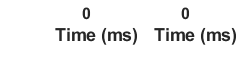

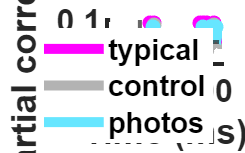


% plotting
cfg.plotting = true;
plot_corr_sig(cfg, d, d.stats.ISC_RSA.pvalMat.onesided, 'uncor');

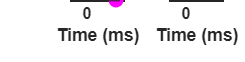

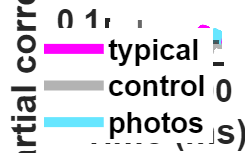

if cfg.FDR
    plot_corr_sig(cfg, d, d.stats.ISC_RSA.pvalMat.onesided.FDR, 'FDR');
end

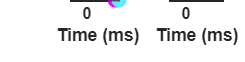

if cfg.cluster
    plot_corr_sig(cfg, d, d.stats.ISC_RSA, 'cluster');
end

### Behavioral data

Out of 2 tests, 2 are significant using a false discovery rate of 0.050000.
FDR/FCR procedure used is guaranteed valid for independent or positively dependent tests.
Out of 25 tests, 25 are significant using a false discovery rate of 0.050000.
FDR/FCR procedure used is guaranteed valid for independent or positively dependent tests.
All  subjects are significant better then chance level.


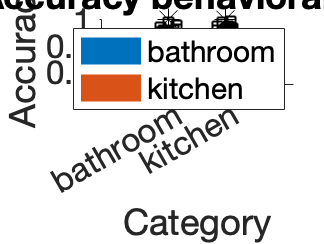

d.beh = beh_task(cfg);

### Stimuli RDM

cfg.dnns = {'vgg16_imagenet'};
% cfg.layer_type = 'late';
cfg.layer_type = 'early_mid_late';
cfg.correlation_type = 'Spearman';
cfg.partial_cor = false;
cfg.dissimilarity = true;
cfg.plot_rdm = false;
cfg.new_figure = true;
cfg.analysis_names = {'stimuli'};
cfg.exp_num = 2;

% Create output directory if wanted
output_dir = fullfile(pwd, '..', 'dnn_features', 'stimuli');
if exist(output_dir, 'dir')
    rmdir(output_dir, 's');
end

if ~exist('images','var')
    images = struct;
end

cfg.predictor_RDMs = {'stimuli_early', 'stimuli_intermediate', 'stimuli_late'};
cfg.RDM_to_partial_out = cfg.predictor_RDMs;
[cfg, d, images] = make_RDM_for_stimuli(cfg, d, images);

Loaded image: labelme_sfxiulhjbhlyiyt.tif
Loaded image: sun_aapitsgbtktqubfy.tif
Loaded image: sun_aavhrsfjbserjtht.tif
Loaded image: sun_abapwbhyhkfixyex.tif
Loaded image: sun_abjtwfukuwddzted.tif
Loaded image: sun_acduarbnmmoglmiv.tif
Loaded image: sun_acegryoqftbzowsg.tif
Loaded image: sun_acgyywnybuveqsro.tif
Loaded image: sun_aclfzgynxzxlbepz.tif
Loaded image: sun_afcoljnjfoxjtgja.tif
Loaded image: sun_aggnnqpdorgxpvce.tif
Loaded image: sun_agguqiubmwhqqunb.tif
Loaded image: sun_aghyqhbptboemmoq.tif
Loaded image: sun_agrwbmhcpmfuwmsg.tif
Loaded image: sun_agyqfjcfkdcydepw.tif
Loaded image: sun_ahaulkltgpkeeemi.tif
Loaded image: sun_ahcvzmoyaycdoftf.tif
Loaded image: sun_ahijqszoswveeyji.tif
Loaded image: sun_ahqjwnzgolcaoidx.tif
Loaded image: sun_ajlawzvmubibwbpy.tif
Loaded image: sun_akiytfaagpdsphgz.tif
Loaded image: sun_aleqenyvunhactkl.tif
Loaded image: sun_aljolscmmzydegqp.tif
Loaded image: sun_alkosphxlxwjwgjd.tif
Loaded image: sun_alotolagknyrgtsk.tif
Loaded image: sun_ambr

### Compare stimuli RDM with pairwise decoding

cfg.save_name = 'compare_tp_RDMs_to_stimuli_RDM'

cfg = struct with fields:
                functionPath: '/Users/theaschmitt/Documents/Data Science/6.Semester/Thesis/pep_wp4_eeg/code/utilities'
                     subNums: [101 102 103 105 106 108 109 110 111 112 113 115 116 117 119 120 122 124 128 129 130 131 133 141 142]
                    FontSize: 20
                           n: 25
                  categories: {'bathroom'  'kitchen'}
                     exp_num: 2
                     nTrials: 100
                     nBlocks: 20
                 trialLength: 0.2500
                   ISC_types: {'pairRep'}
                         dnn: 'vgg16_imagenet'
              analysis_names: {'stimuli'}
                    plotting: 1
                      saving: 1
               dissimilarity: 0
                  classifier: @cosmo_classify_lda
              sourcedataPath: '/Users/theaschmitt/Documents/Data Science/6.Semester/Thesis/pep_wp4_eeg/code/../sourcedata'
                  outputPath: '/Users/theaschmitt/Documents/Data Sc

cfg.dissimilarity = false;
d.stimuli = compare_pairwiseDecodingRDM_with_stimuliRDM(cfg, d);

subject 101
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
subject 102
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
subject 103
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
subject 105
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
subject 106
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
subject 108
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
subject 109
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
subject 110
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
P

### t-test

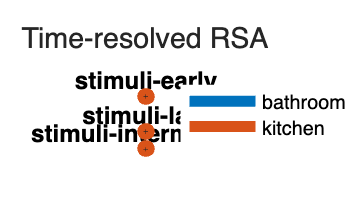

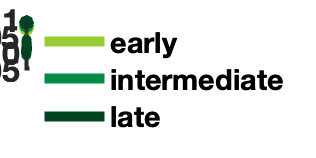

cfg.plotting = true;
cfg.smoothing_window = 5;
cfg.alpha = 0.05;
d.stats.stimuli = stats_ttest_stimuli(cfg,d);

End Message

% finished!
disp([ ...
    newline, ...
    '#########################', ...
    newline, ...
    '####### ALL DONE! #######', ...
    newline, ...
    '#########################', ...
    newline ...
    ]);


#########################
####### ALL DONE! #######
#########################

